clc; clear; close all
format compact

w1 = [2 6];
w2 = [9 11]; % Omit 12 and 13
w3 = [16 20];

h = [7 17]

h =      7    17


hours = h(2) - h(1) - 1

hours = 9


w1_days = w1(2) - w1(1) + 1;
w2_days = w2(2) - w2(1) + 1;
w3_days = w3(2) - w3(1) + 1;

w1_hours = w1_days * hours;
w2_hours = w2_days * hours;
w3_hours = w3_days * hours;

data = load('activations_all_corrected.csv')

data =     10    30    11    27    35
    10    30    11    28    34
    10    30    11    32    17
    10    30    11    33    18
    10    30    11    37     4
    10    30    11    37    33
    10    30    11    40     8
    10    30    11    40    15
    10    30    11    41    30
    10    30    11    43    48



% Activations per hour
data_w1 = zeros(w1_hours, 1);
for i = w1(1):w1(2)
    for ii = h(1):h(2)
        idxs = data(:, 2) == i & data(:, 3) == ii;
        data_w1((i - w1(1)) * hours + ii - h(1) + 1) = sum(idxs);
    end
end
data_w1

data_w1 =     37
    63
    27
    38
    43
    53
    18
    12
    27
    51



data_w2 = zeros(w2_hours, 1);
for i = w2(1):w2(2)
    for ii = h(1):h(2)
        idxs = data(:, 2) == i & data(:, 3) == ii;
        data_w2((i - w2(1)) * hours + ii - h(1) + 1) = sum(idxs);
    end
end
data_w2

data_w2 =     41
    83
    29
    42
    55
    45
    27
    30
    36
    45



data_w3 = zeros(w3_hours, 1);
for i = w3(1):w3(2)
    for ii = h(1):h(2)
        idxs = data(:, 2) == i & data(:, 3) == ii;
        data_w3((i - w3(1)) * hours + ii - h(1) + 1) = sum(idxs);
    end
end
data_w3

data_w3 =     47
    94
    28
    40
    64
    73
    29
    33
    28
    66



% Total number of activations each weak
n_w1 = sum(data_w1);
n_w2 = sum(data_w2);
n_w3 = sum(data_w3);

% Mean activations per hour
mu_w1 = mean(data_w1)

mu_w1 = 36.1064

mu_w2 = mean(data_w2)

mu_w2 = 34.4828

mu_w3 = mean(data_w3)

mu_w3 = 49.0638


% Standard deviation per hour
std_w1 = std(data_w1)

std_w1 = 22.9065

std_w2 = std(data_w2)

std_w2 = 17.4102

std_w3 = std(data_w3)

std_w3 = 40.9031

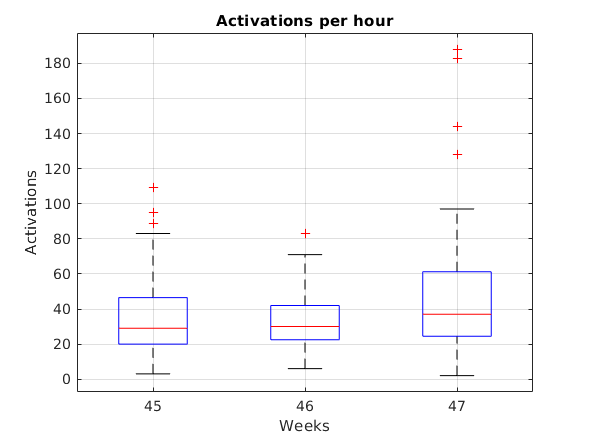


% Boxplot
group = [
    1 * ones(size(data_w1))
    2 * ones(size(data_w2))
    3 * ones(size(data_w3))
];
boxplot([data_w1; data_w2; data_w3], group, "Labels", {45, 46, 47})
grid on
title("Activations per hour")
xlabel("Weeks")
ylabel("Activations")


% Hypothesis tests
disp("Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.")

Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.


disp("W1 not equal to W2")

W1 not equal to W2


[p, h] = ranksum(data_w1, data_w2)

p = 0.8683

h = logical
   0

disp("W1 not equal to W3")

W1 not equal to W3


[p, h] = ranksum(data_w1, data_w3)

p = 0.1219

h = logical
   0


disp("Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.")

Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.


disp("W1 smaller than W3")

W1 smaller than W3


[p, h] = ranksum(data_w1, data_w3, "Tail", "left")

p = 0.0609

h = logical
   0

disp("W2 smaller than W3")

W2 smaller than W3


[p, h] = ranksum(data_w2, data_w3, "Tail", "left")

p = 0.0942

h = logical
   0

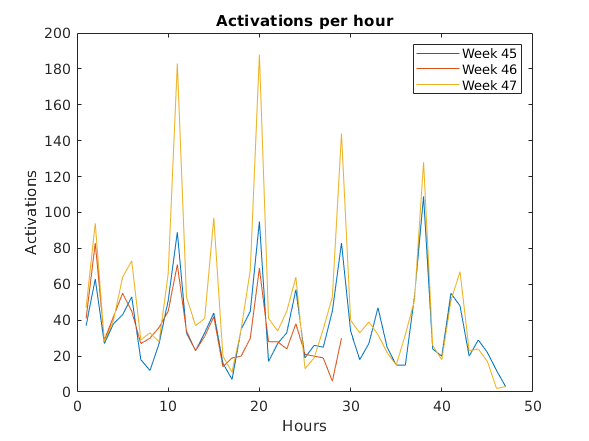


plot(data_w1)
hold on
plot(data_w2)
plot(data_w3)
legend(["Week 45", "Week 46", "Week 47"])
title("Activations per hour")
xlabel("Hours")
ylabel("Activations")
hold off